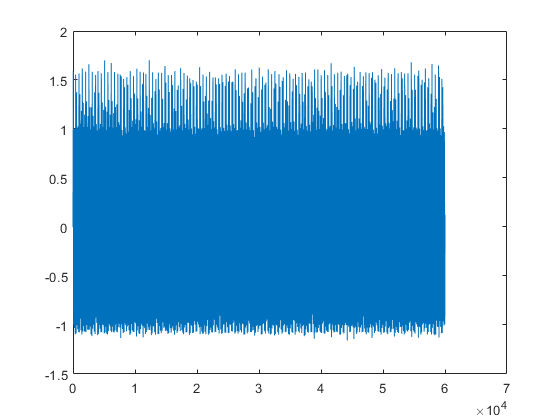

addpath("C:\Users\EQUIPO\Documents\Neuro\ECG_Resp_DataBase");
addpath("C:\Users\EQUIPO\Documents\Neuro\EMG_DataBase");
load bidmc_data.mat

%señales
ECG = data(5).ekg.v;
Resp = data (5).ref.resp_sig.imp.v;

%Offset
ECG_off = ECG - mean(ECG);
Resp_off = Resp - mean(Resp);
% Grafico
n = length(ECG_filt);
t = linspace(0, n/fs, n);
% Generador de ruido
ECG_noise = sin(2*pi*15*t);
Resp_noise = sin(2*pi*8*t);
ECG_noisy = ECG_off + ECG_noise';
Resp_noisy = Resp_off + Resp_noise';
figure
plot(ECG_noisy)

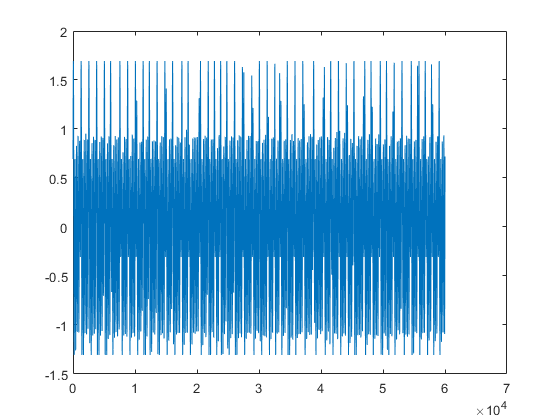

plot(Resp_noisy)

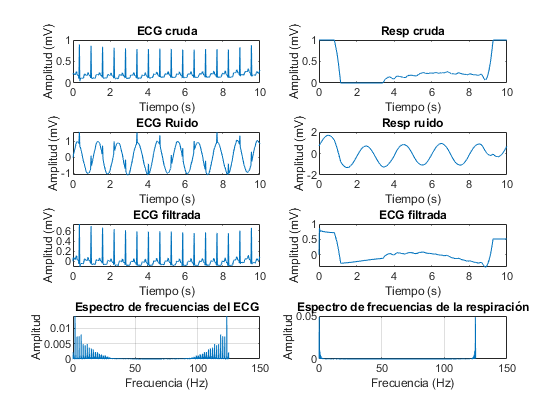


%Filtrado
fs = 125;
d_ECG = designfilt ("bandpassiir","FilterOrder",8,...
    "HalfPowerFrequency1", 0.1,...
    "HalfPowerFrequency2", 50,...
    "SampleRate", fs);

d_Resp = designfilt ("bandpassiir","FilterOrder",8,...
    "HalfPowerFrequency1", 0.1,...
    "HalfPowerFrequency2", 17,...
    "SampleRate", fs);

ECG_filt = filtfilt(d_ECG, ECG_off);
Resp_filt = filtfilt(d_Resp, Resp_off);

% Grafico
n = length(ECG_filt);
t = linspace(0, n/fs, n);

subplot 421
plot (t(1:fs*10), ECG(1:fs*10))
xlabel("Tiempo (s)")
ylabel("Amplitud (mV)")
title("ECG cruda")

subplot 422
plot (t(1:fs*10), Resp(1:fs*10))
xlabel("Tiempo (s)")
ylabel("Amplitud (mV)")
title("Resp cruda")

subplot 423
plot (t(1:fs*10),ECG_noisy(1:fs*10))
xlabel("Tiempo (s)")
ylabel("Amplitud (mV)")
title("ECG Ruido")

subplot 424
plot (t(1:fs*10),Resp_noisy(1:fs*10))
xlabel("Tiempo (s)")
ylabel("Amplitud (mV)")
title("Resp ruido")

subplot 425
plot (t(1:fs*10),ECG_filt(1:fs*10))
xlabel("Tiempo (s)")
ylabel("Amplitud (mV)")
title("ECG filtrada")

subplot 426
plot (t(1:fs*10), Resp_filt(1:fs*10))
xlabel("Tiempo (s)")
ylabel("Amplitud (mV)")
title("ECG filtrada")

% Calculo de la transformada rápida de Fourier (FFT) para el ECG
N_ecg = length(ECG_filt);
f_ecg = (0:N_ecg-1)*(fs/N_ecg);
ecg_fft = abs(fft(ECG_filt)/N_ecg);

% Calculo de la transformada rápida de Fourier (FFT) para la respiración
N_resp = length(Resp_filt);
f_resp = (0:N_resp-1)*(fs/N_resp);
resp_fft = abs(fft(Resp_filt)/N_resp);

% Gráficos
subplot 427
plot(f_ecg, ecg_fft);
title('Espectro de frecuencias del ECG');
xlabel('Frecuencia (Hz)');
ylabel('Amplitud');
grid on;

subplot 428
plot(f_resp, resp_fft);
title('Espectro de frecuencias de la respiración');
xlabel('Frecuencia (Hz)');
ylabel('Amplitud');
grid on;


% Frecuencia fundamental
[~, idx_ecg] = max(ecg_fft);
fundamental_freq_ecg = f_ecg(idx_ecg);
fprintf('Frecuencia fundamental del ECG: %.2f Hz\n', fundamental_freq_ecg);

Frecuencia fundamental del ECG: 1.63 Hz



[~, idx_resp] = max(resp_fft);
fundamental_freq_resp = f_resp(idx_resp);
fprintf('Frecuencia fundamental de la respiración: %.2f Hz\n', fundamental_freq_resp);

Frecuencia fundamental de la respiración: 0.20 Hz



% Estimación de latidos por minuto
bpm_ecg = fundamental_freq_ecg * 60;
fprintf('Latidos por minuto (ECG): %.2f\n', bpm_ecg);

Latidos por minuto (ECG): 97.87



% Estimación de respiraciones por minuto
rpm_resp = fundamental_freq_resp * 60;
fprintf('Respiraciones por minuto: %.2f\n', rpm_resp);

Respiraciones por minuto: 11.75


## EMG

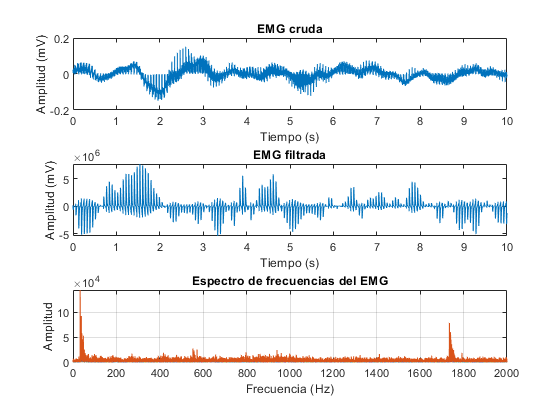

addpath("C:\Users\EQUIPO\Documents\Neuro\EMG_DataBase");
load sub1.mat

%Offset
EMG_off = EMG - mean(EMG);

%Filtrado
fs = 2000;

d_EMG = designfilt ("bandpassiir","FilterOrder",8,...
    "HalfPowerFrequency1", 20,...
    "HalfPowerFrequency2", 1000,...
    "SampleRate", fs);
EMG_filt = filtfilt(d_EMG, EMG_off);

% Grafico
n = length(EMG_filt);
t = linspace(0, n/fs, n);

subplot 311
plot (t(1:fs*10), EMG(1:fs*10))
xlabel("Tiempo (s)")
ylabel("Amplitud (mV)")
title("EMG cruda")

subplot 312
plot (t(1:fs*10),EMG_filt(1:fs*10))
xlabel("Tiempo (s)")
ylabel("Amplitud (mV)")
title("EMG filtrada")

% Calculo de la transformada rápida de Fourier (FFT) para el EMG
N_emg = length(EMG_filt);
f_emg = (0:N_emg-1)*(fs/N_emg);
emg_fft = abs(fft(EMG_filt)/N_emg);

% Gráficos
subplot 313
plot(f_emg ,emg_fft);
title('Espectro de frecuencias del EMG');
xlabel('Frecuencia (Hz)');
ylabel('Amplitud');
grid on;


% Inicializa el contador de puntos máximos
numMaximos = 0;

% Itera a través de la señal de EMG para encontrar los puntos máximos
for i = 2:length(emg_fft)-1
    if emg_fft(i) > emg_fft(i-1) && emg_fft(i) > emg_fft(i+1)
        numMaximos = numMaximos + 1;
    end
end

% Muestra el número de puntos máximos en la señal de EMG
disp(['El número de puntos máximos en la señal de EMG es: ', num2str(numMaximos)]);

El número de puntos máximos en la señal de EMG es: 329
